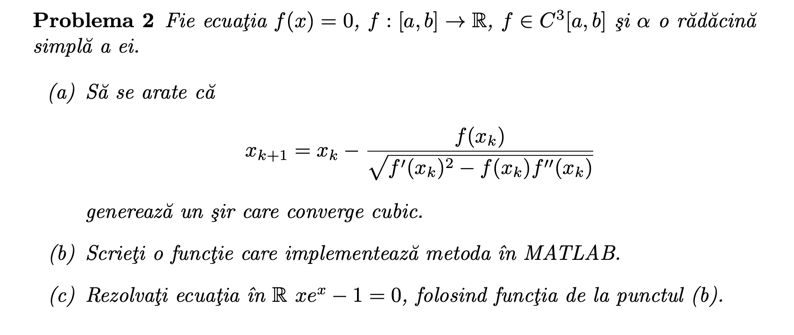

## Rezolvare

### Primul subpunct 

Consideram $f\to \left\lbrack 0,\infty \right\rbrack$, altfel problema n-ar avea sens pe numere reale.

Fie $\phi \left(x\right)=x-\frac{f\left(x\right)}{\sqrt{f^{\prime } {\left(x\right)}^2 -f\left(x\right){f^{\prime } }^{\prime } \left(x\right)}}$. Dorim sa gasim radacina $f\left(x_0 \right)=0$ a functiei f, deci $\phi \left(x_0 \right)=x_0$. Cautam ordinul de convergenta al acestei functii: 

syms f(x) x0;
assume(f(x)>0);
phi(x)=x - f/sqrt(diff(f,x,1)^2 - f*diff(f,x,2))

$$phi(x) = x-\frac{f\left(x\right)}{\sqrt{{\left(\frac{\partial }{\partial x}f\left(x\right)\right)}^{2}-f\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)}}$$

function phi=substituteWithX0(phi, n, f, x, x0)
    syms h(x);
    for i=1:n
        phi=subs(phi,diff(f,x,i),diff(h,x,i));
    end
    phi=subs(phi,f(x),0);
    phi=subs(phi,h,f);
    phi=subs(phi,x,x0);
    phi=simplify(phi);
end

phi_df1=diff(phi, x, 1)

$$phi\_df1(x) = \begin{array}{l} \frac{f\left(x\right)\,\left(\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)\,\frac{\partial }{\partial x}f\left(x\right)-f\left(x\right)\,\frac{\partial^{3}}{\partial x^{3}}f\left(x\right)\right)}{{\sigma_{1}}^{3/2}\,2}-\frac{\frac{\partial }{\partial x}f\left(x\right)}{\sqrt{\sigma_{1}}}+1\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial x}f\left(x\right)\right)}^{2}-f\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}f\left(x\right) \end{array}$$

phi_df1(x0)=substituteWithX0(phi_df1,2,f,x,x0)

$$phi\_df1(x0) = 1-\frac{\frac{\partial }{\partial x_{0}}f\left(x_{0}\right)}{\sqrt{{\left(\frac{\partial }{\partial x_{0}}f\left(x_{0}\right)\right)}^{2}}}$$

Deoarece derivata este pozitiva (?), $\Rightarrow \phi^{\prime } \left(x_0 \right)=0$.

phi_df2=diff(phi, x, 2)

$$phi\_df2(x) = \begin{array}{l} \frac{\sigma_{2}\,\frac{\partial }{\partial x}f\left(x\right)}{{\sigma_{1}}^{3/2}}-\frac{f\left(x\right)\,\left(f\left(x\right)\,\frac{\partial^{4}}{\partial x^{4}}f\left(x\right)-{\left(\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)\right)}^{2}\right)}{{\sigma_{1}}^{3/2}\,2}-\frac{f\left(x\right)\,{\sigma_{2}}^{2}\,3}{{\sigma_{1}}^{5/2}\,4}-\frac{\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)}{\sqrt{\sigma_{1}}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial x}f\left(x\right)\right)}^{2}-f\left(x\right)\,\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial x^{2}}f\left(x\right)\,\frac{\partial }{\partial x}f\left(x\right)-f\left(x\right)\,\frac{\partial^{3}}{\partial x^{3}}f\left(x\right) \end{array}$$

phi_df2(x0)=substituteWithX0(phi_df2,4,f,x,x0)

$$phi\_df2(x0) = 0$$

Deci si ${\phi^{\prime } }^{\prime } \left(x_0 \right)=0$

phi_df3=diff(phi,x,3)

$$phi\_df3(x) = \begin{array}{l} \frac{3\,\sigma_{1}\,\sigma_{7}}{\sigma_{3}}-\frac{3\,\sigma_{2}\,\frac{\partial }{\partial x}f\left(x\right)}{\sigma_{3}}-\frac{f\left(x\right)\,\left(\sigma_{5}\,\frac{\partial }{\partial x}f\left(x\right)-2\,\sigma_{4}\,\sigma_{7}+f\left(x\right)\,\frac{\partial^{5}}{\partial x^{5}}f\left(x\right)\right)}{{\sigma_{6}}^{3/2}\,2}-\frac{9\,{\sigma_{1}}^{2}\,\frac{\partial }{\partial x}f\left(x\right)}{4\,{\sigma_{6}}^{5/2}}-\frac{\sigma_{4}}{\sqrt{\sigma_{6}}}+\frac{f\left(x\right)\,{\sigma_{1}}^{3}\,15}{{\sigma_{6}}^{7/2}\,8}+\frac{f\left(x\right)\,\sigma_{1}\,\sigma_{2}\,9}{{\sigma_{6}}^{5/2}\,4}\\ \mathrm{where}\\ \sigma_{1}=\sigma_{7}\,\frac{\partial }{\partial x}f\left(x\right)-f\left(x\right)\,\sigma_{4}\\ \sigma_{2}=f\left(x\right)\,\sigma_{5}-{\sigma_{7}}^{2}\\ \sigma_{3}=2\,{\sigma_{6}}^{3/2}\\ \sigma_{4}=\frac{\partial^{3}}{\partial x^{3}}f\left(x\right)\\ \sigma_{5}=\frac{\partial^{4}}{\partial x^{4}}f\left(x\right)\\ \sigma_{6}={\left(\frac{\partial }{\partial x}f\left(x\right)\right)}^{2}-f\left(x\right)\,\sigma_{7}\\ \sigma_{7}=\frac{\partial^{2}}{\partial x^{2}}f\left(x\right) \end{array}$$

phi_df3(x0)=substituteWithX0(phi_df3,5,f,x,x0)

$$phi\_df3(x0) = \frac{\left(3\,{\left(\frac{\partial^{2}}{\partial {x_{0}}^{2}}f\left(x_{0}\right)\right)}^{2}-4\,\frac{\partial^{3}}{\partial {x_{0}}^{3}}f\left(x_{0}\right)\,\frac{\partial }{\partial x_{0}}f\left(x_{0}\right)\right)\,{\left(\frac{\partial }{\partial x_{0}}f\left(x_{0}\right)\right)}^{3}}{4\,{\left({\left(\frac{\partial }{\partial x_{0}}f\left(x_{0}\right)\right)}^{2}\right)}^{5/2}}$$

Observam ca aici nu se mai reduc argumentele, deci ${{\phi^{\prime } }^{\prime } }^{\prime } \left(x_0 \right)\not= 0\ldotp$

$\phi^{\prime } \left(x_0 \right)={\phi^{\prime } }^{\prime } \left(x_0 \right)=0,{{\phi^{\prime } }^{\prime } }^{\prime } \left(x_0 \right)\not= 0\Rightarrow$ ordinul de convergenta al sirului $x_n$ este 3 $\Rightarrow$ sirul converge cubic.

### Al doilea subpunct

function [x1,val_f,i]=NewtonV2(f,df,ddf,x0,err,NrMaxIt)
    if nargin < 6, NrMaxIt=100; end
    if nargin < 5, err=1e-12; end
    
    for i=1:NrMaxIt
        x1=x0-f(x0)/sqrt(df(x0)^2 - f(x0)*ddf(x0));
        if norm(f(x1),Inf)<err||norm(x1-x0,Inf)<err...
                ||norm(x1-x0,Inf)/norm(x1,Inf)<err
            val_f=f(x1);
            return;
        end
        x0=x1;
    end
    val_f=f(x1);
end

### Al treilea subpunct

syms x;
f=x*exp(x)-1

$$f = x\,{\mathrm{e}}^{x}-1$$

df=diff(f,x,1)

$$df = {\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x}$$

ddf=diff(f,x,2)

$$ddf = 2\,{\mathrm{e}}^{x}+x\,{\mathrm{e}}^{x}$$

f=matlabFunction(f);
df=matlabFunction(df);
ddf=matlabFunction(ddf);

[x, val_f, nr_it]=NewtonV2(f,df,ddf,0)

x =          0.567143290409784


val_f =      0


nr_it =      3


c0=fzero(f, 0)

c0 =          0.567143290409784
